# Test 3: Multi-layered and spherically-symmetric (Io)

In this notebook the tidal response of a multi-layered, spherically-symmetric, viscoelastic body is computed using LOV3D and compared against results obtained with the [code](https://github.com/mroviranavarro/Poroviscoelastic_Tides) of [Rovira-Navarro et al. 2022](https://doi.org/10.1029/2021JE007117) ([code](https://github.com/mroviranavarro/Poroviscoelastic_Tides))

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior model

The interior model is based on the Io model of [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001), which consists on a core, mantle, asthenosphere and lithosphere. Two different interior models are considered

- Interior Model A: Tidal heating only occurs in the asthenosphere 

- Interior Model B: Tidal heating occurs in both asthenosphere and deep mantle 

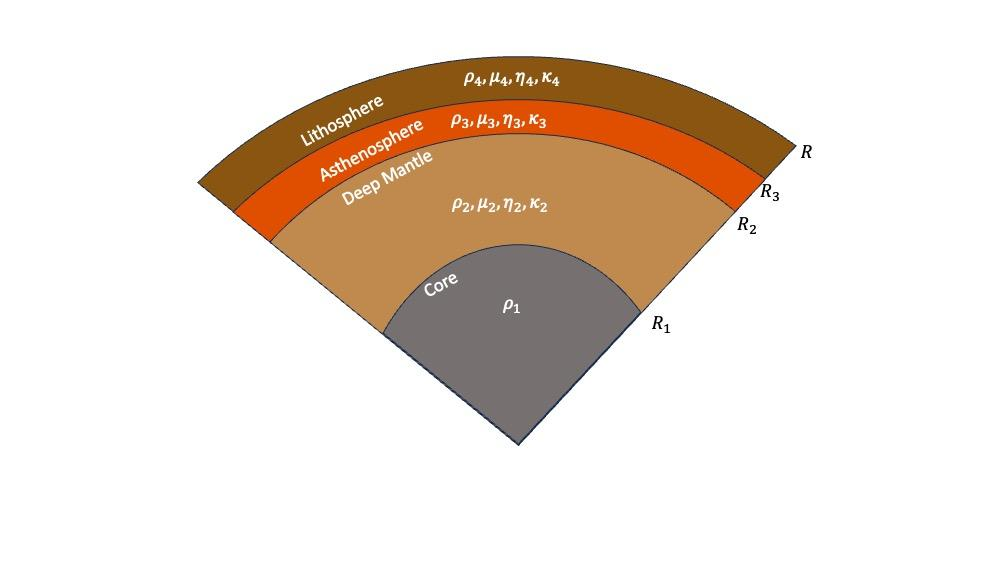

The model parameters are given in dimensional form 

% Values are taken from Steinke et al. (2020a)
omega0=4.1086E-05; %Io's orbital frequency 
T=2*pi/omega0; %Io's orbital period
% Interior model A, asthenosphere only heating 
% Interior_Model goes from core (1) to surface (n) with indices
% Interior_Model values for the core
Interior_Model_A(1).R0 = 965; % CMB in km 
Interior_Model_A(1).rho0 = 5150; % average density in kg m^-3
Interior_Model_A(1).rho0_2 = 5150; % rho_2 in kg m^-3 (used for icy moons)
% Interior_Model values for mantle
Interior_Model_A(2).R0 = 1591.6; % outer radius of this layer
Interior_Model_A(2).rho0 = 3244; % density in kg m^-3
Interior_Model_A(2).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_A(2).mu0 = 6e10; % shear modulus in Pa
Interior_Model_A(2).eta0 = 1e20; % viscosity in Pa s
% Interior_Model values for asthenosphere
Interior_Model_A(3).R0 = 1791.6; % outer radius of this layer
Interior_Model_A(3).rho0 = 3244; % density in kg m^-3
Interior_Model_A(3).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_A(3).mu0 = 7.8e5; % shear modulus in Pa
Interior_Model_A(3).eta0 = 1e11; % viscosity in Pa s
% Interior_Model values for mantle
Interior_Model_A(4).R0 = 1821.6; % outer radius of this layer
Interior_Model_A(4).rho0 = 3244; % density in kg m^-3
Interior_Model_A(4).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_A(4).mu0 = 6.5e10; % shear modulus in Pa
Interior_Model_A(4).eta0 = 1e23; % viscosity in Pa s
% Interior model B, mixed heating
% Interior_Model values for the core
Interior_Model_B(1).R0 = 965; % CMB in km 
Interior_Model_B(1).rho0 = 5150; % average density in kg m^-3
Interior_Model_B(1).rho0_2 = 5150; % rho_2 in kg m^-3 (used for icy moons)
% Interior_Model values for mantle
Interior_Model_B(2).R0 = 1591.6; % outer radius of this layer
Interior_Model_B(2).rho0 = 3244; % density in kg m^-3
Interior_Model_B(2).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_B(2).mu0 = 2e9; % shear modulus in Pa
Interior_Model_B(2).eta0 = 8e14; % viscosity in Pa s
% Interior_Model values for asthenosphere
Interior_Model_B(3).R0 = 1791.6; % outer radius of this layer
Interior_Model_B(3).rho0 = 3244; % density in kg m^-3
Interior_Model_B(3).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_B(3).mu0 = 9e7; % shear modulus in Pa
Interior_Model_B(3).eta0 = 3.5e12; % viscosity in Pa s
% Interior_Model values for mantle
Interior_Model_B(4).R0 = 1821.6; % outer radius of this layer
Interior_Model_B(4).rho0 = 3244; % density in kg m^-3
Interior_Model_B(4).Ks0 = 200e12; % bulk modulus in Pa
Interior_Model_B(4).mu0 = 6.5e10; % shear modulus in Pa
Interior_Model_B(4).eta0 = 1e23; % viscosity in Pa s


## Define forcing

The forcing potential is defined

Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model_A); % number of concentric layers. Including the core!
Numerics.method = 'variable'; % method of setting the radial points per layer, here fixed number of layers
Numerics.Nrbase = 2000; % depending on the method this will determine the number of points per layer
%code parallelization
Numerics.parallel_sol = 1; % Calculate the solution using a parfor-loop either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files using parfor-loops either 0 or 1
% lateral variations
Numerics.perturbation_order = 2; %maximum order to which couplings are considered
Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 1; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model_A,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  2000  2000  2000
BCindices: 2001  4001  6001
Nr: 6000
 


## Compute the tidal response 

The tidal response is obtained for models A and B 

% write interior model in the right format for the code
Interior_Model_A= get_rheology(Interior_Model_A,Numerics,Forcing);

No lateral variations provided, I will assume the layer is spherically-symmetric
No lateral variations provided, I will assume the layer is spherically-symmetric
No lateral variations provided, I will assume the layer is spherically-symmetric


Interior_Model_B= get_rheology(Interior_Model_B,Numerics,Forcing);

No lateral variations provided, I will assume the layer is spherically-symmetric
No lateral variations provided, I will assume the layer is spherically-symmetric
No lateral variations provided, I will assume the layer is spherically-symmetric


[Love_Spectra_A,y_A]=get_Love(Interior_Model_A,Forcing,Numerics,'verbose');

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL -----------
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    9.65000e+02    5.15000e+03    0    -
2    1.59160e+03    3.24400e+03    6.00000e+10    2.00000e+14 1.00000e+20
3    1.79160e+03    3.24400e+03    7.80000e+05    2.00000e+14 1.00000e+11
4    1.82160e+03    3.24400e+03    6.50000e+10    2.00000e+14 1.00000e+23
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.52975    1.5875    0    -
2    0.87374    1    0.92308    3076.9231 10060.0615
3    0.98353    1    1.2e-05    3076.9231 1.006e-05
4    1    1    1    3076.9231 10060061.526
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
3    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
4    (0,

[Love_Spectra_B,y_B]=get_Love(Interior_Model_B,Forcing,Numerics,'verbose');

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL -----------
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    9.65000e+02    5.15000e+03    0    -
2    1.59160e+03    3.24400e+03    2.00000e+09    2.00000e+14 8.00000e+14
3    1.79160e+03    3.24400e+03    9.00000e+07    2.00000e+14 3.50000e+12
4    1.82160e+03    3.24400e+03    6.50000e+10    2.00000e+14 1.00000e+23
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.52975    1.5875    0    -
2    0.87374    1    0.030769    3076.9231 0.08048
3    0.98353    1    0.0013846    3076.9231 0.0003521
4    1    1    1    3076.9231 10060061.526
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
3    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
4    (0,

## Comparison of k2 Love numbers

The values obtained with the spherically-symmetric poroviscoealstic [code](https://github.com/mroviranavarro/Poroviscoelastic_Tides) are: 

- Model A: 0.733721707307109 - 0.015123675091503i

- Model B: 0.611841605660674 - 0.015009557001099i

disp(['k_2 Model A ' num2str(Love_Spectra_A.k)])

k_2 Model A 0.73372-0.015124i


disp(['k_2 Model B ' num2str(Love_Spectra_B.k)])

k_2 Model B 0.61184-0.01501i
